% fieldinfo0p94K = import manually data from "field_info.txt"
fieldinfo0p94K.FileName = strcat("HH0_",num2str(fieldinfo0p94K.FileID));
for i=1:length(fieldinfo0p94K.FileName)
    tbl2 = ImportNeutronsLineCut(strcat(fieldinfo0p94K.FileName(i,:),".txt"));
%     i = i+length(fieldsOrtho);
    nDatap94(i).file = fieldinfo0p94K.FileName(i,:);
    nDatap94(i).hh0 = tbl2.hh0;
    nDatap94(i).I = tbl2.I;
    nDatap94(i).dI = tbl2.dI;
    nDatap94(i).field = fieldinfo0p94K.H_T(i);
    nDatap94(i).temp = fieldinfo0p94K.T_K(i);
end

i=67;
hh067 = nDatap94(i).hh0;
I67 = nDatap94(i).I;
dI = nDatap94(i).dI;

Error using ENS_peak_fit_function (line 45)
Error while evaluating Figure CreateFcn.

Error using newplot (line 73)
Error while evaluating Axes CreateFcn.



     General model Gauss2:
     y(x) =  a1*exp(-((x-b1)/c1)^2) + a2*exp(-((x-b2)/c2)^2)
     Coefficients (with 95% confidence bounds):
       a1 =    2.86e+06  (2.605e+06, 3.114e+06)
       b1 =      -8.018  (-8.019, -8.017)
       c1 =     0.01427  (0.0127, 0.01585)
       a2 =   5.848e+06  (5.622e+06, 6.074e+06)
       b2 =      -7.972  (-7.972, -7.971)
       c2 =      0.0184  (0.01752, 0.01929)


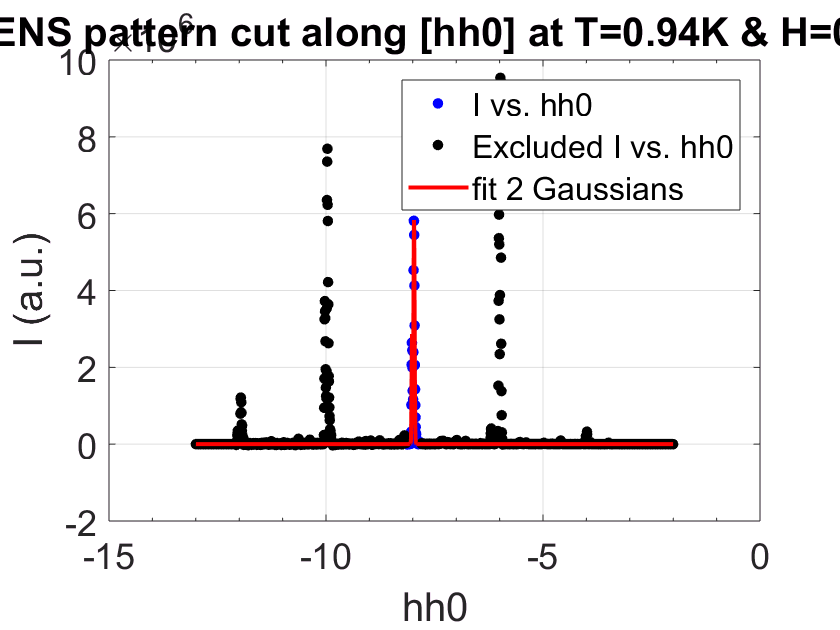

hc = -8;% value of h in reciprocal space
H = extractfield(nDatap94,'field');
for i=1%:length(H)
% for i=length(fieldinfo0p94K.H_T(fieldinfo0p94K.H_T<0.75))
    [nDatap94(i).fitrslt, nDatap94(i).gof] = ENS_peak_fit_gauss2(...
        nDatap94(i).hh0,nDatap94(i).I,hc);
    title(strcat("ENS pattern cut along [hh0] at T=",num2str(round(nDatap94(i).temp,2)),...
        "K & H=",num2str(nDatap94(i).field),"T"))
    disp(nDatap94(i).fitrslt)
    if nDatap94(i).fitrslt.a1<0 | nDatap94(i).fitrslt.a2<0
       nDatap94(i).fitrslt=[];
       nDatap94(i).gof=[];
       break
    end
end

lsplt = 30;
for i=1:length(H)
    if isequal(nDatap94(i).fitrslt,[])
        lsplt = i-1;
        break
    end
    nDatap94(i).a1 = nDatap94(i).fitrslt.a1;
    nDatap94(i).b1 = nDatap94(i).fitrslt.b1;
    nDatap94(i).c1 = nDatap94(i).fitrslt.c1;
    nDatap94(i).a2 = nDatap94(i).fitrslt.a2;
    nDatap94(i).b2 = nDatap94(i).fitrslt.b2;
    nDatap94(i).c2 = nDatap94(i).fitrslt.c2;
    levelCfd = 2*tcdf(-1,nDatap94(i).gof.dfe);% level of confidence of fit
    cft = confint(nDatap94(i).fitrslt,1-levelCfd);% confidence interval of fit
    stdC1= (cft(2,2)-cft(1,2))/2;% standard error on parameter b1
    stdC2= (cft(2,5)-cft(1,5))/2;% standard error on parameter b2
    nDatap94(i).splitting = abs(nDatap94(i).fitrslt.b2-nDatap94(i).fitrslt.b1)/8;
    nDatap94(i).dsplt = (stdC2+stdC1)/8;
end

ntDatap94 = struct2table(nDatap94);

hh0p85 = nDatap94(67).hh0;
Ip85 = nDatap94(67).I;

Msplit = cell2mat(ntDatap94.splitting);% convert splitting table into array
Mdsplit = cell2mat(ntDatap94.dsplt);% same with error bars
MH = H(1:lsplt);% field array with same length as splitting array
avgtemp = round(mean(ntDatap94.temp),2);% average temperature of the full dataset

A = 5.7e-3; Hc = 0.88;% fit parameters determined from Curve Fitting Tool
fsplit = @(x) A*sqrt(1-(x/Hc)^2);% fitting function
figure
fplot(fsplit,'-r','LineWidth',2);% plot fit

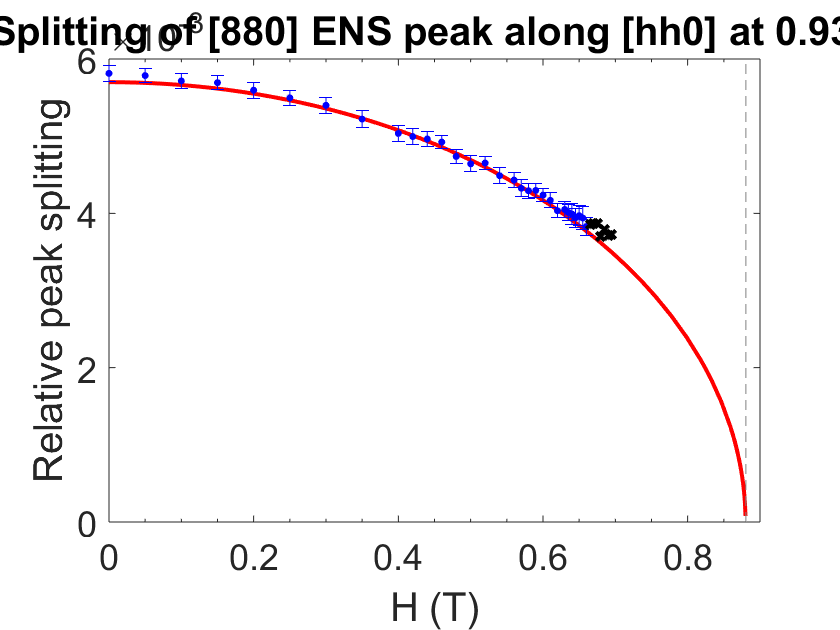

hold on
indsep = 30;% index of last element used for fit
errorbar(MH(1:indsep),Msplit(1:indsep),Mdsplit(1:indsep),'.b','MarkerSize',12);% plot data
plot(MH(indsep+1:end),Msplit(indsep+1:end),'xk','MarkerSize',6);% plot exclude data points
xlim([0 0.9]); ylim([0 6e-3]);
title(strcat("Splitting of [880] ENS peak along [hh0] at ",num2str(avgtemp),"K"))
xlabel("H (T)");ylabel("Relative peak splitting");

## Fit with single Gaussian above Hc

     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.681e+06  (6.465e+06, 6.897e+06)
       b1 =      -7.993  (-7.993, -7.992)
       c1 =     0.01823  (0.01755, 0.01891)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.607e+06  (6.383e+06, 6.832e+06)
       b1 =      -7.993  (-7.993, -7.992)
       c1 =     0.01871  (0.01797, 0.01944)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.677e+06  (6.453e+06, 6.902e+06)
       b1 =      -7.993  (-7.993, -7.992)
       c1 =     0.01869  (0.01797, 0.01942)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =     6.7e+06  (6.467e+06, 6.933e+06)
       b1 =      -7.993  (-7.993, -7.992)
       c1 =     0.01871  (0.01795, 0.01946)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.713e+06  (6.486e+06, 6.939e+06)
       b1 =      -7.993  (-7.993, -7.992)
       c1 =     0.01853  (0.01781, 0.01925)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =    6.59e+06  (6.379e+06, 6.801e+06)
       b1 =      -7.993  (-7.993, -7.992)
       c1 =     0.01881  (0.01812, 0.01951)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.654e+06  (6.434e+06, 6.874e+06)
       b1 =      -7.992  (-7.993, -7.992)
       c1 =     0.01898  (0.01825, 0.0197)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.655e+06  (6.45e+06, 6.86e+06)
       b1 =      -7.992  (-7.993, -7.992)
       c1 =     0.01916  (0.01848, 0.01984)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.677e+06  (6.464e+06, 6.891e+06)
       b1 =      -7.993  (-7.993, -7.992)
       c1 =     0.01901  (0.01831, 0.01971)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.708e+06  (6.481e+06, 6.935e+06)
       b1 =      -7.992  (-7.993, -7.992)
       c1 =      0.0193  (0.01855, 0.02006)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.655e+06  (6.434e+06, 6.876e+06)
       b1 =      -7.992  (-7.993, -7.992)
       c1 =     0.01954  (0.01879, 0.02029)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.824e+06  (6.638e+06, 7.011e+06)
       b1 =      -7.992  (-7.993, -7.992)
       c1 =     0.01933  (0.01872, 0.01994)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.776e+06  (6.579e+06, 6.972e+06)
       b1 =      -7.992  (-7.992, -7.992)
       c1 =     0.01945  (0.0188, 0.02011)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.753e+06  (6.532e+06, 6.973e+06)
       b1 =      -7.992  (-7.993, -7.992)
       c1 =     0.01958  (0.01884, 0.02032)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.867e+06  (6.667e+06, 7.066e+06)
       b1 =      -7.992  (-7.992, -7.991)
       c1 =     0.01971  (0.01905, 0.02037)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.671e+06  (6.487e+06, 6.855e+06)
       b1 =      -7.992  (-7.992, -7.991)
       c1 =     0.02011  (0.01947, 0.02075)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.668e+06  (6.497e+06, 6.839e+06)
       b1 =      -7.991  (-7.992, -7.991)
       c1 =     0.02027  (0.01967, 0.02087)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.828e+06  (6.659e+06, 6.997e+06)
       b1 =      -7.991  (-7.992, -7.991)
       c1 =     0.02012  (0.01955, 0.0207)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.692e+06  (6.495e+06, 6.888e+06)
       b1 =      -7.991  (-7.992, -7.991)
       c1 =     0.02079  (0.02009, 0.0215)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.655e+06  (6.481e+06, 6.83e+06)
       b1 =      -7.991  (-7.991, -7.991)
       c1 =      0.0212  (0.02056, 0.02185)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   7.018e+06  (6.831e+06, 7.206e+06)
       b1 =      -7.991  (-7.991, -7.99)
       c1 =     0.02012  (0.0195, 0.02075)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   7.005e+06  (6.851e+06, 7.159e+06)
       b1 =      -7.991  (-7.991, -7.991)
       c1 =     0.02061  (0.02008, 0.02113)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   7.063e+06  (6.894e+06, 7.233e+06)
       b1 =       -7.99  (-7.991, -7.99)
       c1 =     0.02032  (0.01976, 0.02088)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.655e+06  (6.492e+06, 6.819e+06)
       b1 =       -7.99  (-7.99, -7.99)
       c1 =     0.02171  (0.02109, 0.02232)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.992e+06  (6.814e+06, 7.17e+06)
       b1 =       -7.99  (-7.99, -7.989)
       c1 =     0.02097  (0.02036, 0.02159)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.655e+06  (6.478e+06, 6.833e+06)
       b1 =       -7.99  (-7.99, -7.989)
       c1 =     0.02177  (0.0211, 0.02244)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   7.011e+06  (6.855e+06, 7.167e+06)
       b1 =      -7.989  (-7.99, -7.989)
       c1 =     0.02134  (0.02079, 0.02189)


     General model Gauss1:
     y(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   6.731e+06  (6.588e+06, 6.874e+06)
       b1 =      -7.989  (-7.99, -7.989)
       c1 =      0.0218  (0.02127, 0.02234)


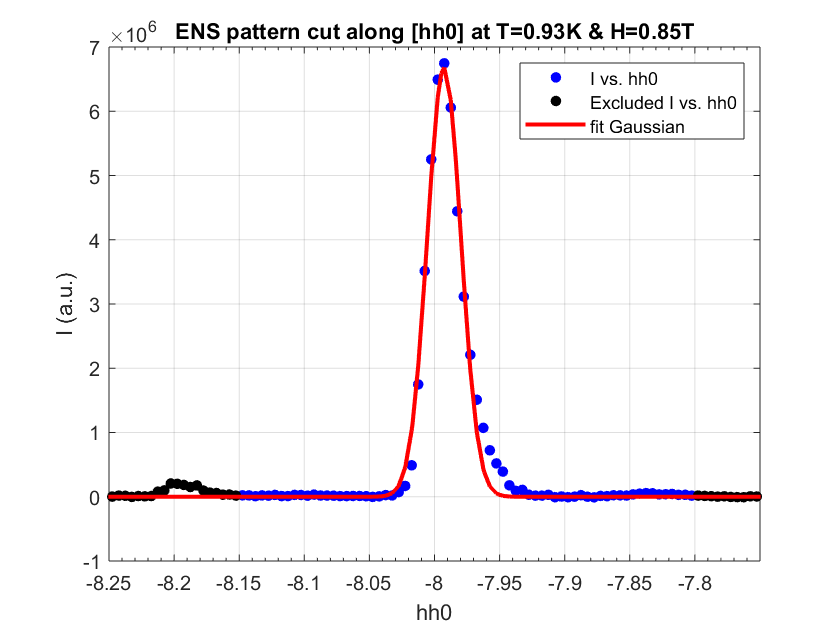

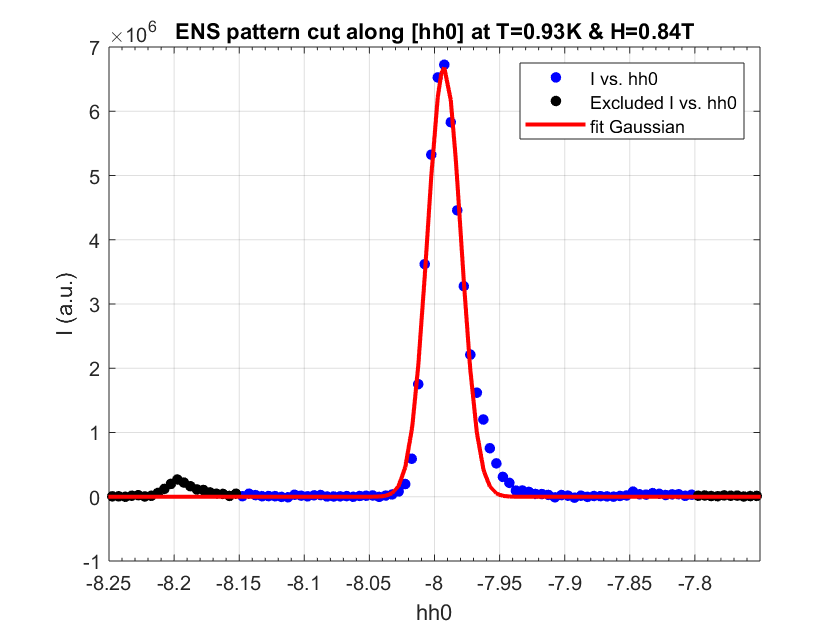

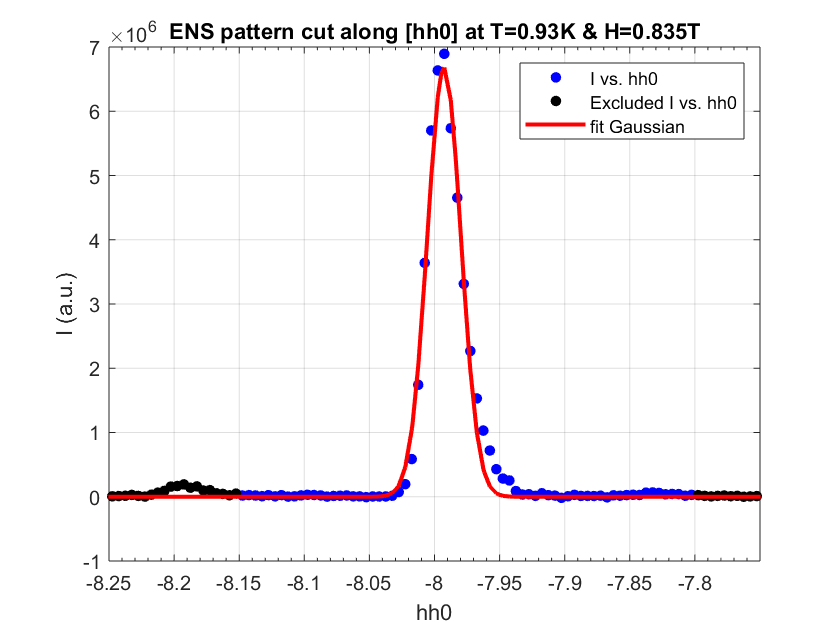

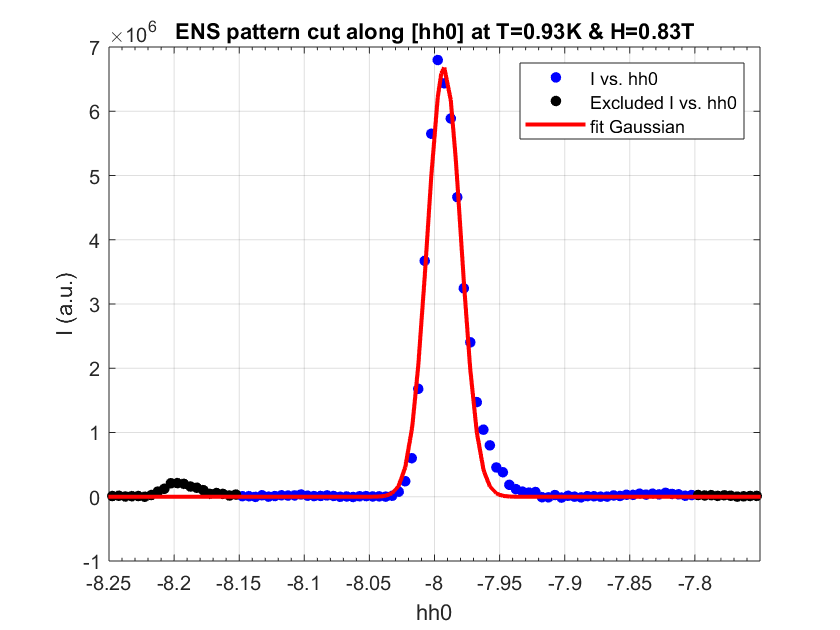

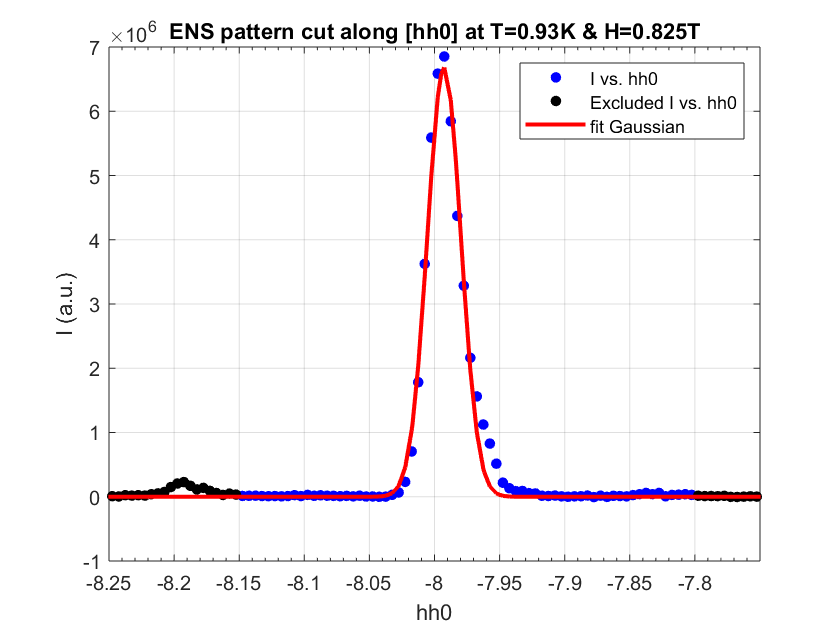

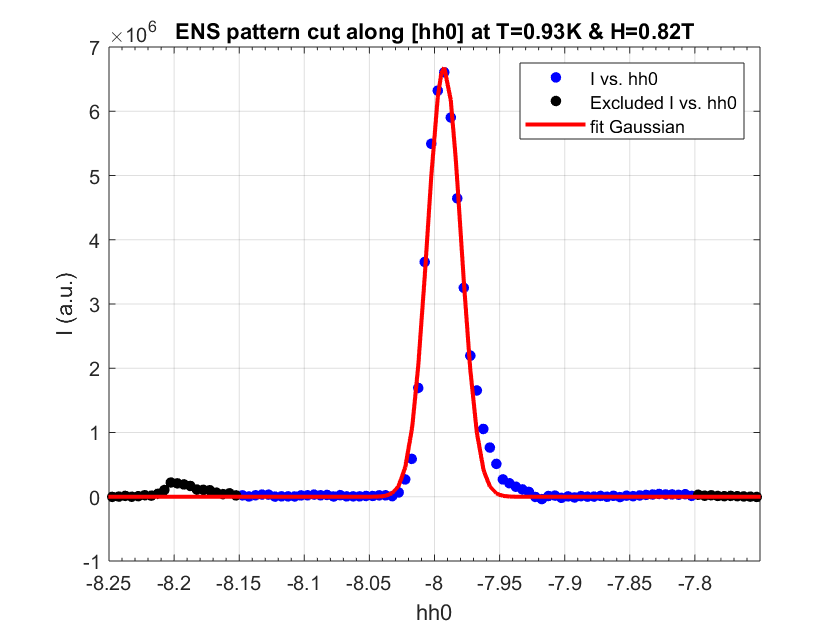

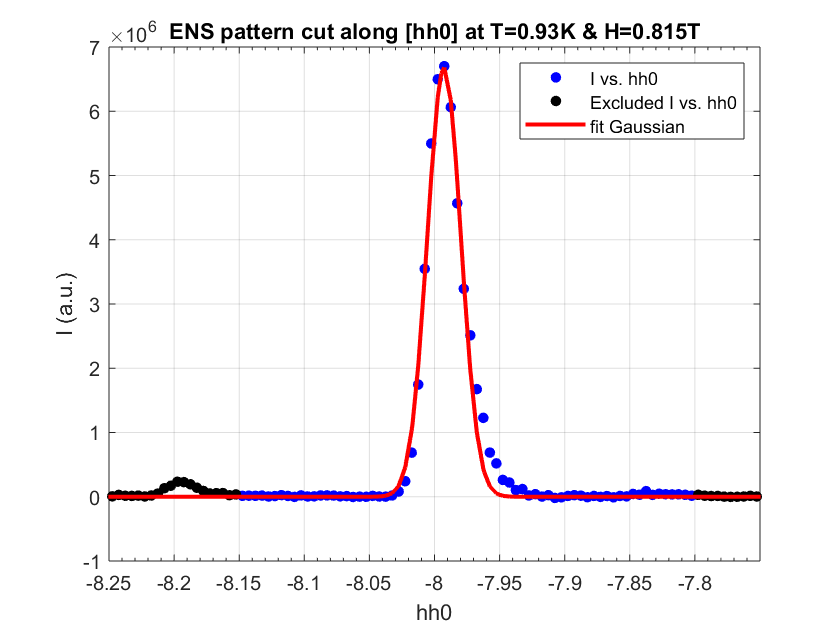

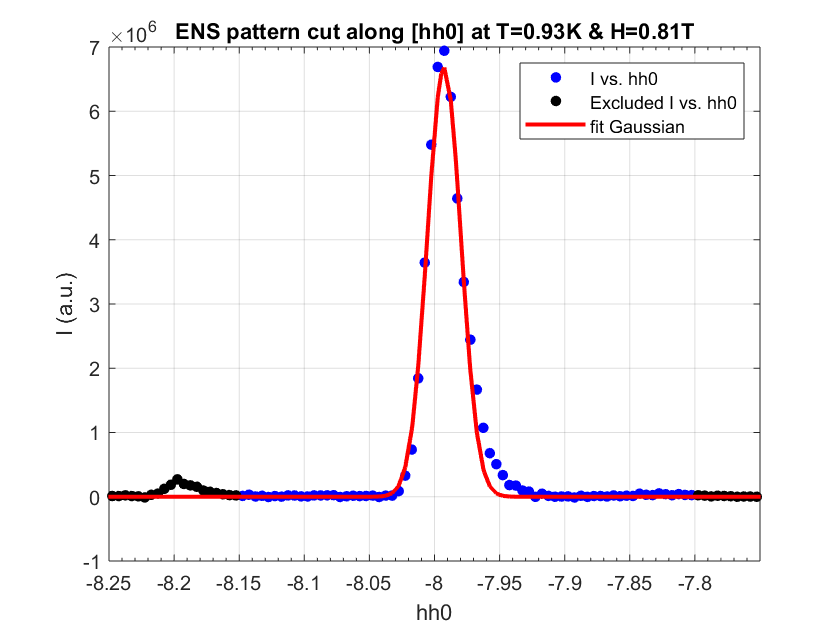

for i=length(H)%:-1:40
    [xData, yData] = prepareCurveData(nDatap94(i).hh0,nDatap94(i).I);
    dataExcl = nDatap94(i).hh0<hc-.15 | nDatap94(i).hh0>hc+0.2;
    ft = fittype( 'gauss1' );
    excludedPoints = excludedata( xData, yData, 'Indices', dataExcl );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.Lower = [0 -Inf 0];
    opts.StartPoint = [6e6 hc 0.01];
    opts.Exclude = excludedPoints;
    % Fit model to data.
    [nDatap94(i).fit1, nDatap94(i).gof1] = fit( xData, yData, ft, opts );
    % Plot
    figure
    h = plot( fitresult, xData, yData, excludedPoints, '.k');
    legend( h, 'I vs. hh0', 'Excluded I vs. hh0', 'fit Gaussian', 'Location', 'NorthEast' );
    title(strcat("ENS pattern cut along [hh0] at T=",num2str(round(nDatap94(i).temp,2)),...
        "K & H=",num2str(nDatap94(i).field),"T"))
    xlabel("hh0");ylabel("I (a.u.)");
    xlim([hc-.25 hc+.25]);
    grid on
    disp(nDatap94(i).fit1)
end

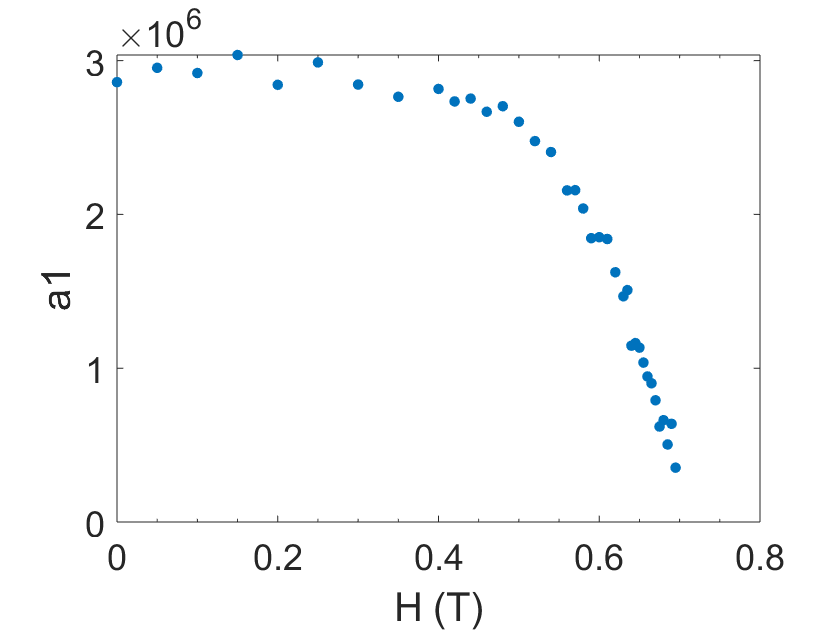

figure
plot(H(1:lsplt),extractfield(nDatap94,'a1'),'.')
xlabel("H (T)");ylabel("a1");

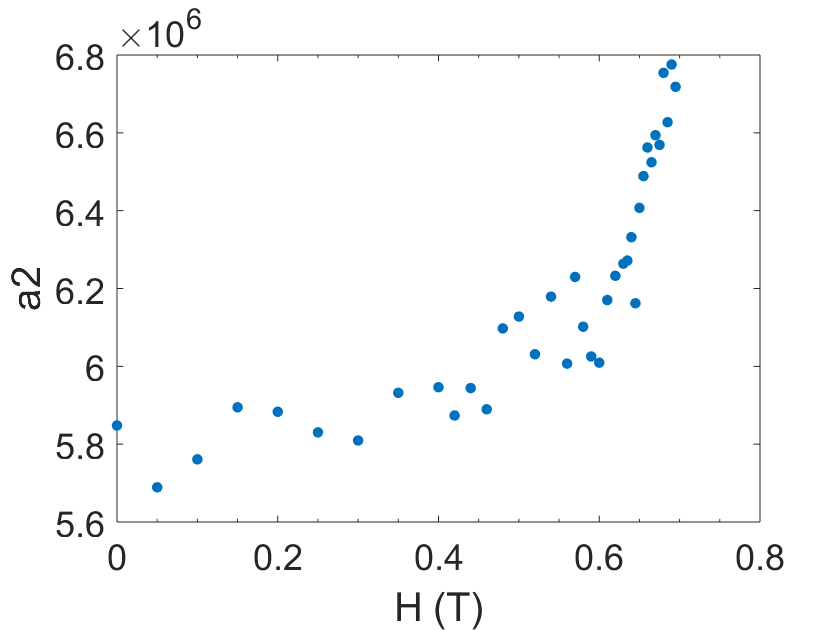

figure
plot(H(1:lsplt),extractfield(nDatap94,'a2'),'.')
xlabel("H (T)");ylabel("a2");

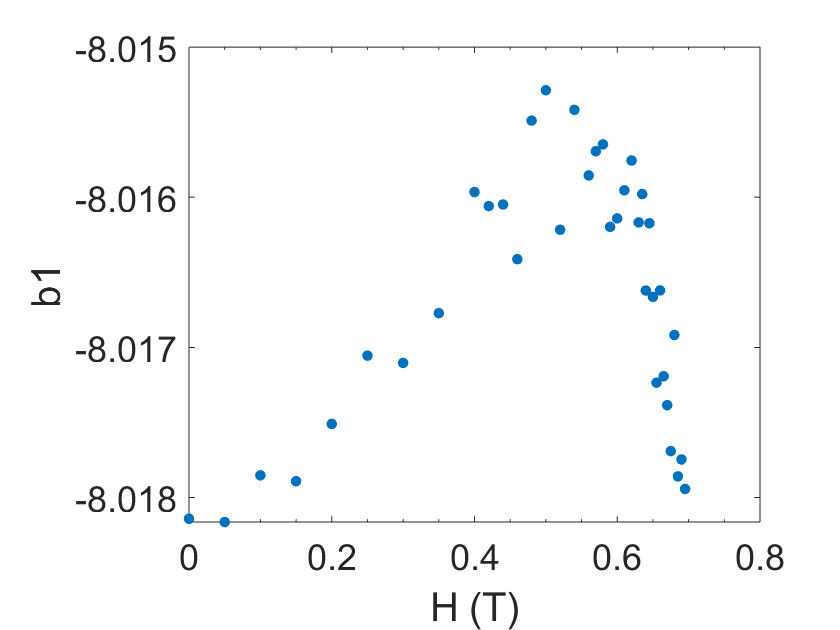

figure
plot(H(1:lsplt),extractfield(nDatap94,'b1'),'.')
xlabel("H (T)");ylabel("b1");

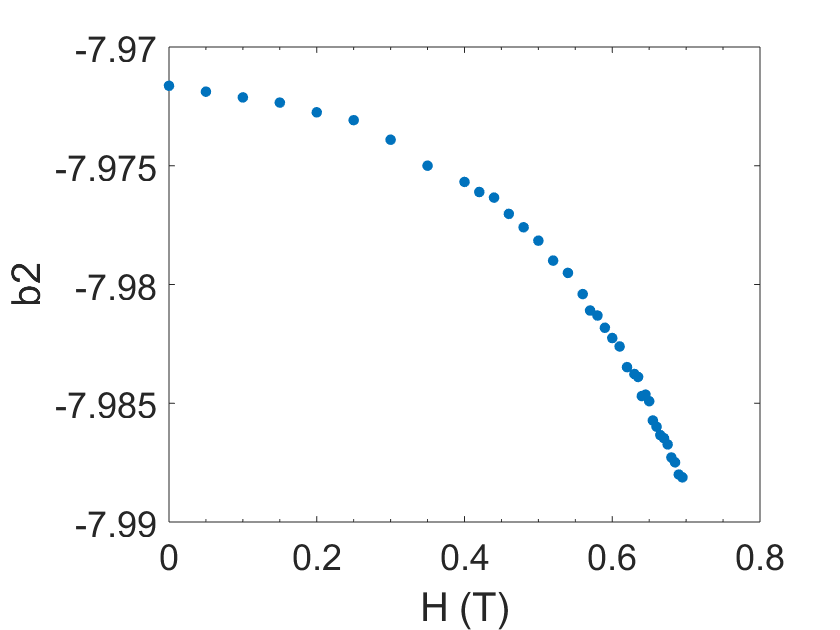

figure
plot(H(1:lsplt),extractfield(nDatap94,'b2'),'.')
xlabel("H (T)");ylabel("b2");

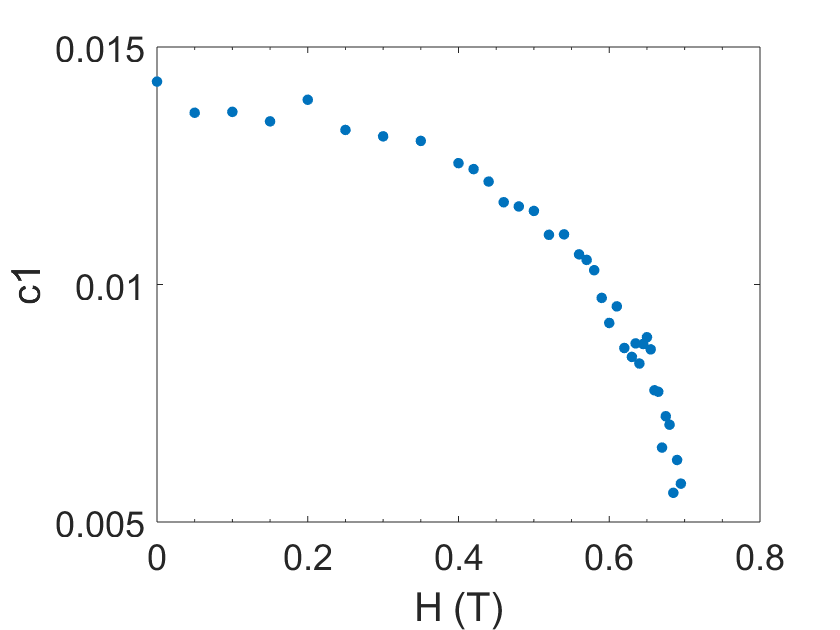

figure
plot(H(1:lsplt),extractfield(nDatap94,'c1'),'.')
xlabel("H (T)");ylabel("c1");

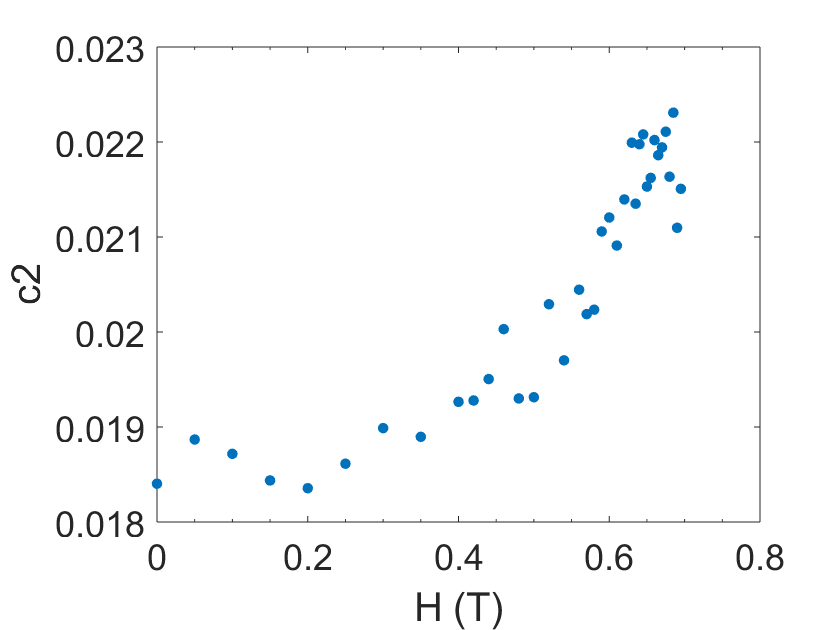

figure
plot(H(1:lsplt),extractfield(nDatap94,'c2'),'.')
xlabel("H (T)");ylabel("c2");